# Ensemble Averaging

## 2.1. Signal with multiple measurements 

### Preliminaries 

clear all; clc;

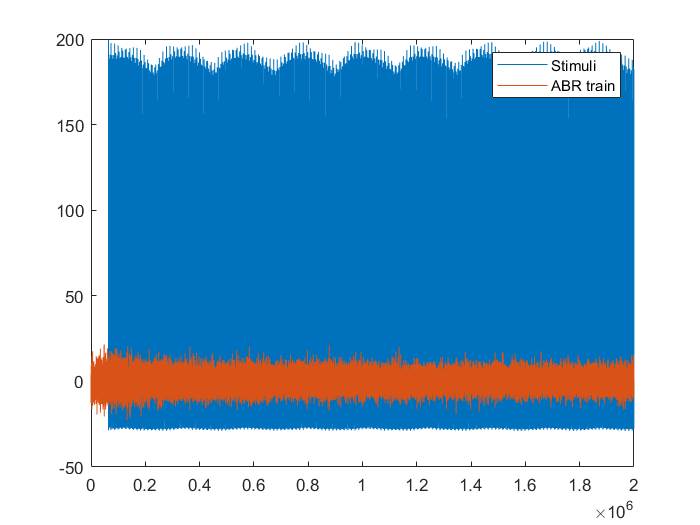

load("ABR_rec.mat");
ABR = ABR_rec(:,2);
auditory_pulses = ABR_rec(:,1);

figure; %plot the responses
plot(ABR_rec);
legend('Stimuli','ABR train');

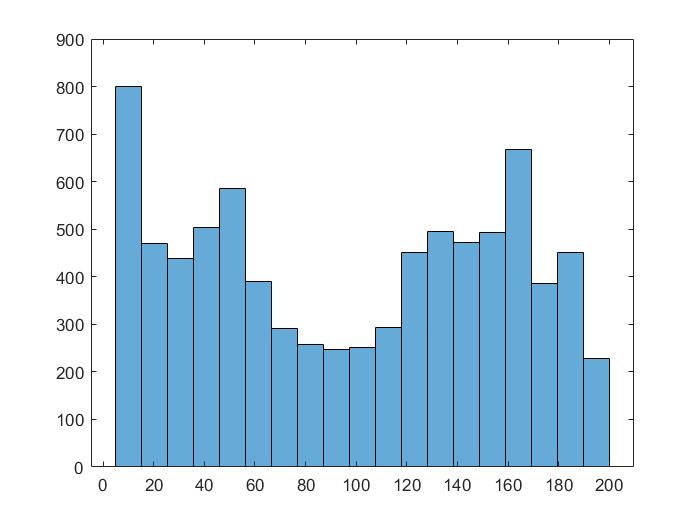

figure; %plot the auditory pulses
histogram(auditory_pulses, 'BinLimits', [5, 200]); %Finding a value to threshold

%and identify pulses.
thresh = find(auditory_pulses>100); 

%Extracts stimulus points
j=1;  
for i=1:length(thresh)-1  
    if thresh(i+1)-thresh(i)>1 
        stim_point(j,1)=thresh(i+1); j=j+1; 
    end  
end

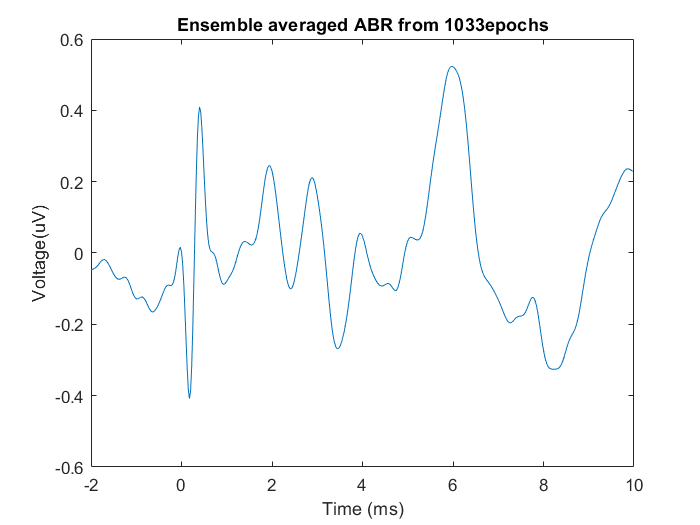

%Extracts corresponding array of signals
j = 0;  
for i=1:length(stim_point) j = j + 1; 
    epochs(:,j) = ABR_rec((stim_point(i)-80:stim_point(i)+399),2);  
end 

ensmbl_avg = mean(epochs(:,(1:length(stim_point))),2); 
% calculates mean across
% coloumns giving a single coloumn as the result.

figure, 
plot((-80:399)/40,ensmbl_avg);
xlabel('Time (ms)'), ylabel('Voltage(uV)');
title(['Ensemble averaged ABR from ',num2str(length(epochs)),'epochs']);

### Improvement of the SNR 

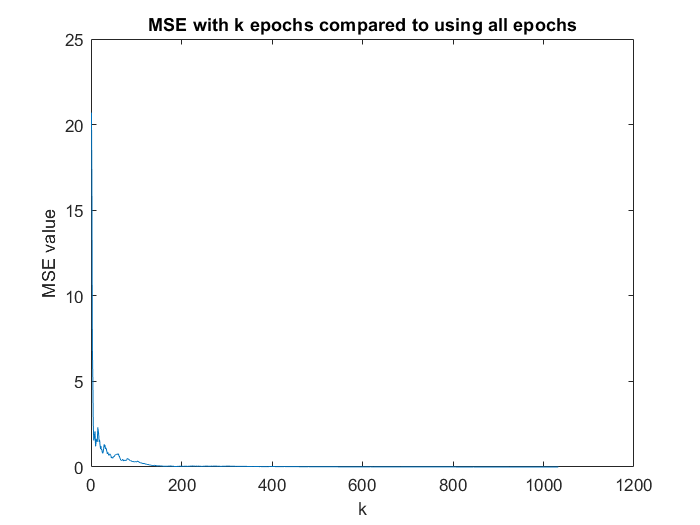

% Calculating MSE with increasing the number of averaged ABRs

mse_k = nan(1,length(epochs(1,:)));

for i = 1:length(mse_k)
    y_k =  mean(epochs(:,(1:i)),2);
    mse_k(i) = mse(ensmbl_avg,y_k);
end

figure, 
plot(1:length(mse_k), mse_k);
xlabel('k'), ylabel('MSE value');
title(['MSE with k epochs compared to using all epochs']);

As the number of epochs increase by a factor of N, the compared to the initial signal, the variance of noise affecting the signal reduces by a factor of N. Therefore, we can see with the number of epochs, variance has lowered, causing a lesser MSE. Here, we consider the ABR response a deterministic signal.

## 2.2. Signal with repetitive patterns 

### Viewing the signal and addition of Gaussian white noise 

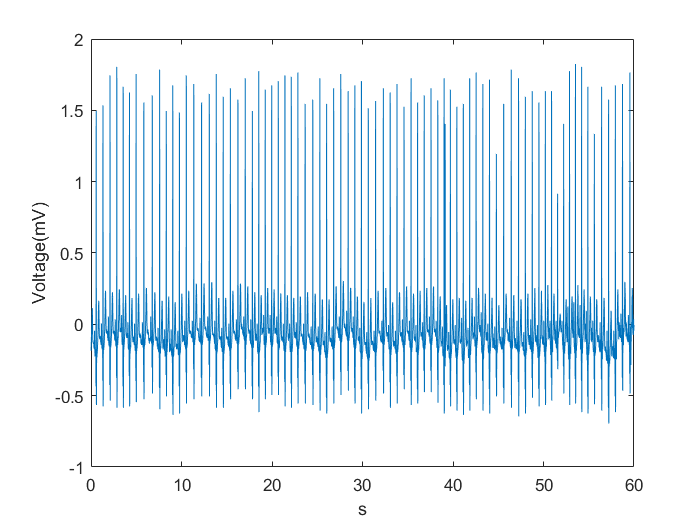

% Loading the signal and adding noise

load("ECG_rec.mat");

figure, 
plot((1:length(ECG_rec))/128, ECG_rec);
xlabel('s'), ylabel('Voltage(mV)');

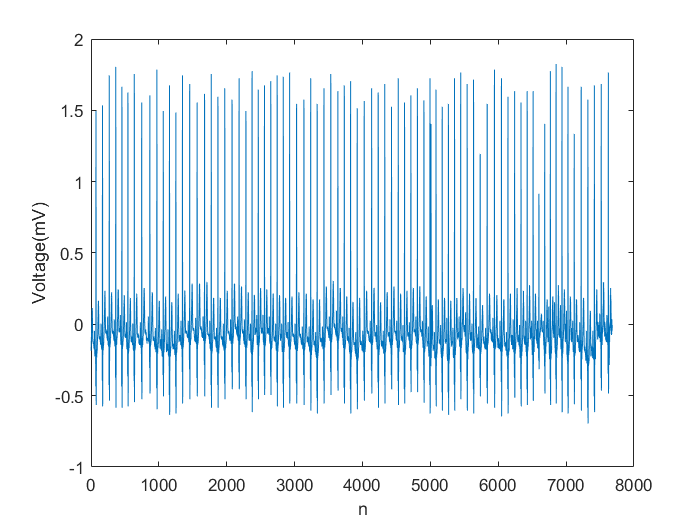


figure, 
plot((1:length(ECG_rec)), ECG_rec);
xlabel('n'), ylabel('Voltage(mV)');

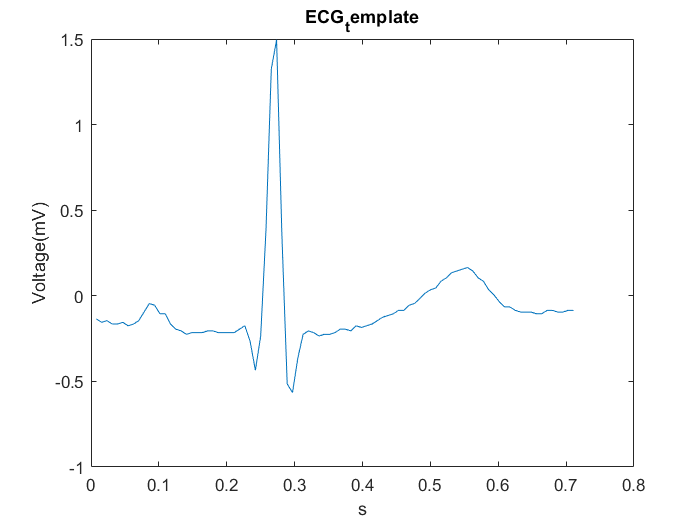


ECG_template = ECG_rec(40:130);
nECG = awgn(ECG_rec,5,'measured');

plot((1:length(ECG_template))/128, ECG_template);
xlabel('s'), ylabel('Voltage(mV)');
title('ECG_template');

### Segmenting ECG into separate epochs and ensemble averaging 

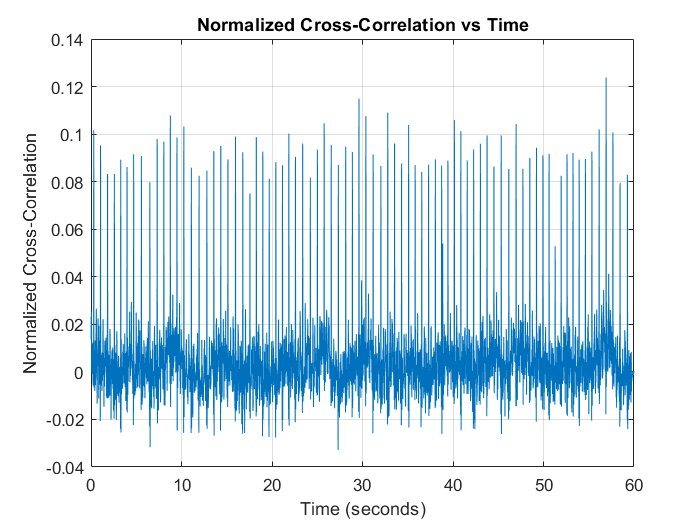

% Calculating normalized correlation between template and nECG

[corr,lags] = xcorr(ECG_template, nECG);
normalization_factor = sqrt(sum(ECG_template.^2)*sum(nECG.^2));

normalized_corr = corr/normalization_factor;

normalized_corr_ = normalized_corr(1:length(nECG)); %take the region
% nECG coincides
normalized_corr_time = flip(normalized_corr_);
% filp to adjust to time axis

delay = flip(abs(lags(1:length(nECG))));
%get the corresponding lags to plot

figure;
plot(delay/128, normalized_corr_time);
xlabel('Time (seconds)');
ylabel('Normalized Cross-Correlation');
title('Normalized Cross-Correlation vs Time');
grid on;

thresh_ecg = find(normalized_corr_time>0.05); % To identify locations with 
%high correlation

j=1;  
for i=1:length(thresh_ecg)-1  %Extracts peak correlation points
% ensure that these high correlation points are not adjacent points

    if thresh_ecg(i+1)-thresh_ecg(i)>1 
        peak_point(j,1)=thresh_ecg(i+1); j=j+1; 
    end  
end


ecg_epochs = nan(length(ECG_template),length(peak_point)-1);

  %Extracts corresponding array of signals
for k=1:length(peak_point)-1
    array_x = nECG(peak_point(k):(peak_point(k)+length(ECG_template)-1));  
    ecg_epochs(:,k) = array_x;
end 


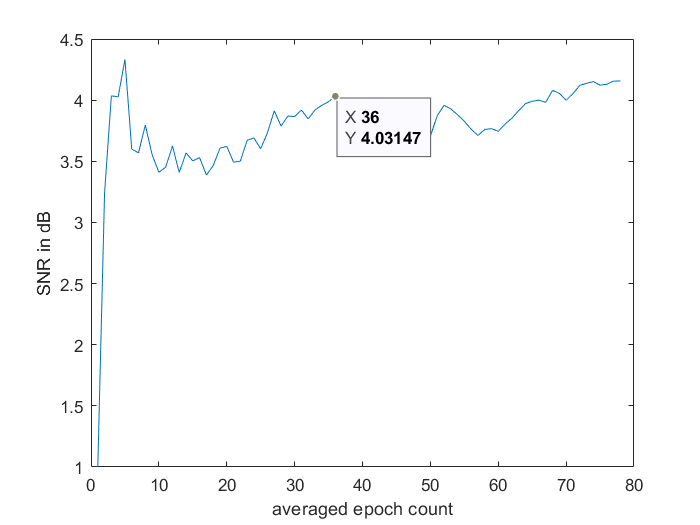

%performs ensemble averaging with the extracted ECGs.

for i = 1:(length(peak_point)-1)
    ensembled_ecg =  mean(ecg_epochs(:,(1:i)),2);
    snr_with_i_averaging(i) = snr_with_noisy_signal(ECG_template,ensembled_ecg');
end

figure;
plot(1:length(ecg_epochs(1,:)), snr_with_i_averaging);
xlabel('averaged epoch count');
ylabel('SNR in dB');

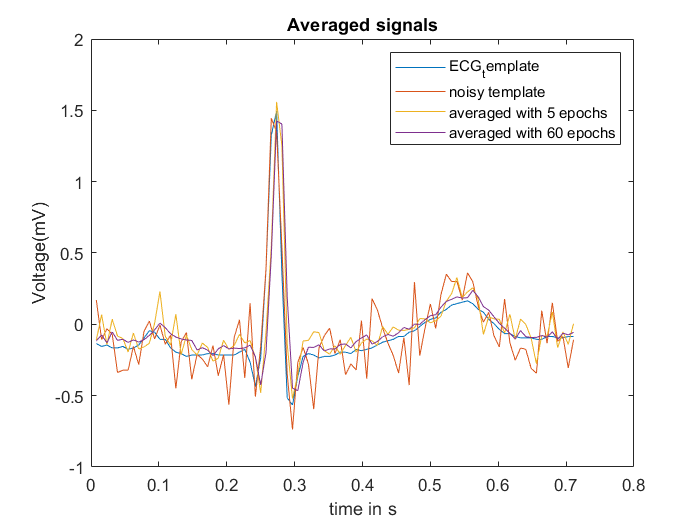

% Plotting the averaged signals
figure;
plot((1:length(ECG_template))/128, ECG_template);
hold on;

plot((1:length(ECG_template))/128, nECG(40:130));
hold on;

plot((1:length(ECG_template))/128, mean(ecg_epochs(:,(1:5)),2));
hold on;

plot((1:length(ECG_template))/128, mean(ecg_epochs(:,(1:60)),2));

xlabel('time in s');
ylabel('Voltage(mV)');
title('Averaged signals');
legend('ECG_template','noisy template','averaged with 5 epochs','averaged with 60 epochs');